Cross Flow Range Values

%load data
batch2 = load("10-24-24mM-try2.mat", "batch_flowrate_list", "time_list");
batch3 = load("10-31-24mM-try3.mat", "batch_flowrate_list", "time_list");
batch5 = load("11-02-24mM-try5.mat", "batch_flowrate_list", "time_list");
batch10 = load("11-10-24mM-try10.mat", "batch_flowrate_list", "time_list");
batch11 = load("11-11-24mM-try-11.mat", "batch_flowrate_list", "time_list");
batch12 = load("11-16-24mM-try12.mat", "batch_flowrate_list", "time_list");
batch14 = load("11-19-24mM-try14.mat", "batch_flowrate_list", "time_list");
batch15 = load("11-20-24mM-try15.mat", "batch_flowrate_list", "time_list");
batch16 = load("11-26-24mM-try16.mat", "batch_flowrate_list", "time_list");

%low pass filter data
batch2.batch_flowrate_list = lowpass(batch2.batch_flowrate_list,.001);
batch3.batch_flowrate_list = lowpass(batch3.batch_flowrate_list,.001);
batch5.batch_flowrate_list = lowpass(batch5.batch_flowrate_list,.001);
batch10.batch_flowrate_list = lowpass(batch10.batch_flowrate_list,.001);
batch11.batch_flowrate_list = lowpass(batch11.batch_flowrate_list,.001);
batch12.batch_flowrate_list = lowpass(batch12.batch_flowrate_list,.001);
batch14.batch_flowrate_list = lowpass(batch14.batch_flowrate_list,.001);
batch15.batch_flowrate_list = lowpass(batch15.batch_flowrate_list,.001);
batch16.batch_flowrate_list = lowpass(batch16.batch_flowrate_list,.001);

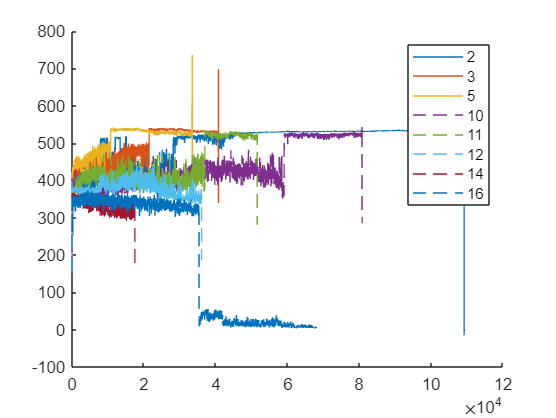

%plot whole data range
clf;
hold on
plot(batch2.batch_flowrate_list)
plot(batch3.batch_flowrate_list)
plot(batch5.batch_flowrate_list)
plot(batch10.batch_flowrate_list,"--")
plot(batch11.batch_flowrate_list,"--")
plot(batch12.batch_flowrate_list,"--")
plot(batch14.batch_flowrate_list,"--")
plot(batch16.batch_flowrate_list,"--")
legend('2','3','5','10','11','12','14','16')

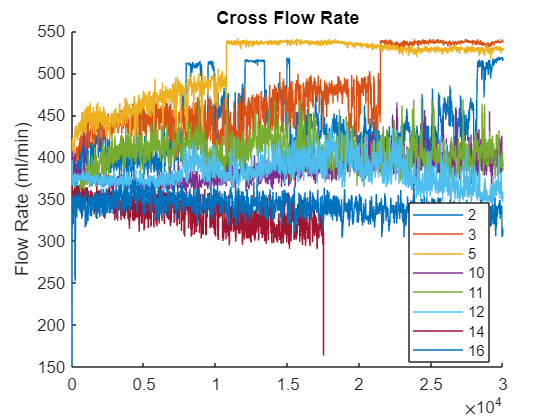

%plot clipped data range (0, 30000)
clf;
hold on
plot(batch2.batch_flowrate_list)
plot(batch3.batch_flowrate_list)
plot(batch5.batch_flowrate_list)
plot(batch10.batch_flowrate_list)
plot(batch11.batch_flowrate_list)
plot(batch12.batch_flowrate_list)
plot(batch14.batch_flowrate_list)
plot(batch16.batch_flowrate_list)
legend('2','3','5','10','11','12','14','16','Location', 'best')
xlim([0, 30000])
ylabel("Flow Rate (ml/min)")
title("Cross Flow Rate")

%get rid of outliers (values less than 200)
batch2_clipped = batch2.batch_flowrate_list(batch2.batch_flowrate_list > 200);
batch3_clipped = batch3.batch_flowrate_list(batch3.batch_flowrate_list > 200);
batch5_clipped = batch5.batch_flowrate_list(batch5.batch_flowrate_list > 200);
batch10_clipped = batch10.batch_flowrate_list(batch10.batch_flowrate_list > 200);
batch11_clipped = batch11.batch_flowrate_list(batch11.batch_flowrate_list > 200);
batch12_clipped = batch12.batch_flowrate_list(batch12.batch_flowrate_list > 200);
batch14_clipped = batch14.batch_flowrate_list(batch14.batch_flowrate_list > 200);
batch16_clipped = batch16.batch_flowrate_list(batch16.batch_flowrate_list > 200);

%get mean of flowrate
batch2_clipped_mean = mean(batch2_clipped);
batch3_clipped_mean = mean(batch3_clipped);
batch5_clipped_mean = mean(batch5_clipped);
batch10_clipped_mean = mean(batch10_clipped);
batch11_clipped_mean = mean(batch11_clipped);
batch12_clipped_mean = mean(batch12_clipped);
batch14_clipped_mean = mean(batch14_clipped);
batch16_clipped_mean = mean(batch16_clipped);

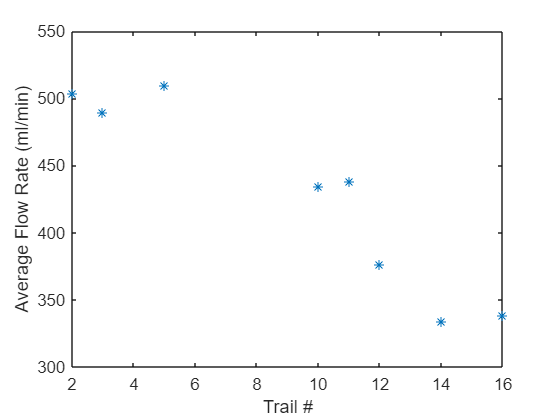

%plot means
clf;
trailNumbers = [2,3,5,10,11,12,14,16];
plot(trailNumbers, [batch2_clipped_mean, batch3_clipped_mean, batch5_clipped_mean, batch10_clipped_mean, ...
    batch11_clipped_mean, batch12_clipped_mean, batch14_clipped_mean, ...
    batch16_clipped_mean],"*")
xlabel('Trail #')
ylabel('Average Flow Rate (ml/min)')

%snip values only until scale time
scale_time = [526,900,746,111,127,360,231,720]*60;
batch2_prescale = batch2.batch_flowrate_list(batch2.time_list < scale_time(1));
batch3_prescale = batch3.batch_flowrate_list(batch3.time_list < scale_time(2));
batch5_prescale = batch5.batch_flowrate_list(batch5.time_list < scale_time(3));
batch10_prescale = batch10.batch_flowrate_list(batch10.time_list < scale_time(4));
batch11_prescale = batch11.batch_flowrate_list(batch11.time_list < scale_time(5));
batch12_prescale = batch12.batch_flowrate_list(batch12.time_list < scale_time(6));
batch14_prescale = batch14.batch_flowrate_list(batch14.time_list < scale_time(7));
batch16_prescale = batch16.batch_flowrate_list(batch16.time_list < scale_time(8));

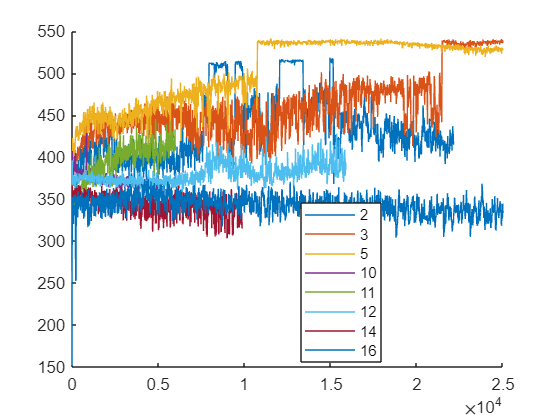

%plot only until scale time
clf;
hold on
plot(batch2_prescale)
plot(batch3_prescale)
plot(batch5_prescale)
plot(batch10_prescale)
plot(batch11_prescale)
plot(batch12_prescale)
plot(batch14_prescale)
plot(batch16_prescale)
legend('2','3','5','10','11','12','14','16','Location', 'best')
xlim([0 25000])

%get mean of flowrate before scale time
batch2_prescale_mean = mean(batch2_prescale);
batch3_prescale_mean = mean(batch3_prescale);
batch5_prescale_mean = mean(batch5_prescale);
batch10_prescale_mean = mean(batch10_prescale);
batch11_prescale_mean = mean(batch11_prescale);
batch12_prescale_mean = mean(batch12_prescale);
batch14_prescale_mean = mean(batch14_prescale);
batch16_prescale_mean = mean(batch16_prescale);

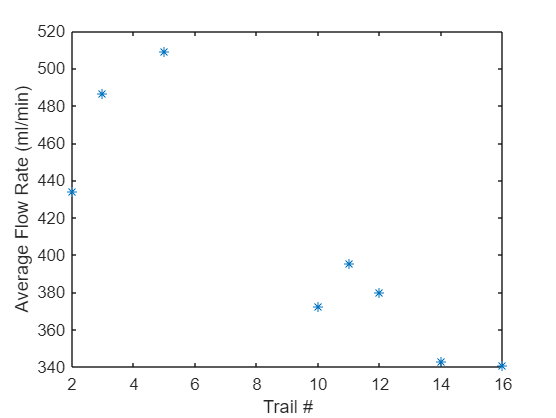

%plot mean prescale times
clf;
trailNumbers = [2,3,5,10,11,12,14,16];
plot(trailNumbers, [batch2_prescale_mean, batch3_prescale_mean, batch5_prescale_mean, batch10_prescale_mean, ...
    batch11_prescale_mean, batch12_prescale_mean, batch14_prescale_mean, ...
    batch16_prescale_mean],"*")
xlabel('Trail #')
ylabel('Average Flow Rate (ml/min)')

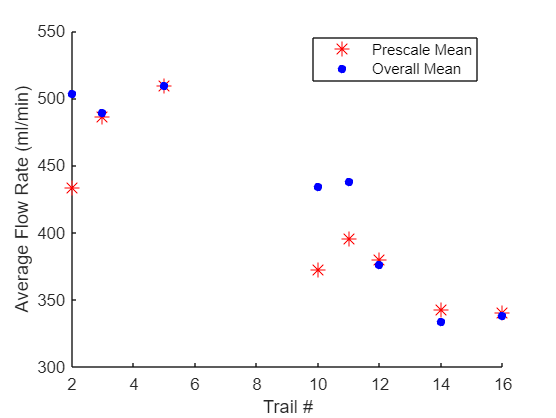

%compare prescale mean and overall mean time
clf;
hold on
trailNumbers = [2,3,5,10,11,12,14,16];
plot(trailNumbers, [batch2_prescale_mean, batch3_prescale_mean, batch5_prescale_mean, batch10_prescale_mean, ...
    batch11_prescale_mean, batch12_prescale_mean, batch14_prescale_mean, ...
    batch16_prescale_mean],"r*", 'MarkerSize',9)
plot(trailNumbers, [batch2_clipped_mean, batch3_clipped_mean, batch5_clipped_mean, batch10_clipped_mean, ...
    batch11_clipped_mean, batch12_clipped_mean, batch14_clipped_mean, ...
    batch16_clipped_mean],"b.",'MarkerSize',15)
legend("Prescale Mean", "Overall Mean", "Location","best")
xlabel('Trail #')
ylabel('Average Flow Rate (ml/min)')